run('sim_init.mlx')

   USAGE: PLECS('CMD','PARAMETER1','PARAMETER2',...)
     Known commands are: get, set, version, hostid, thermal, scope, checkout


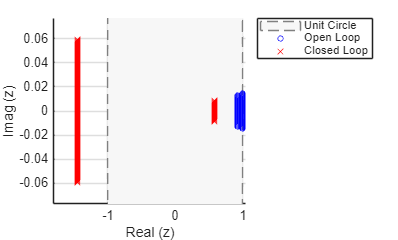

plot_LGR(KF)

function plot_LGR(KF)
%PLOT_POLE_MAP_FINAL Plots the root locus of the machine and the filter.
%   Displays Open Loop vs Closed Loop poles and the Unit Circle with external legend.

    % Create figure (slightly wider to accommodate external legend)
    figure
    hold on; grid on;

    % --- 1. Draw Unit Circle (Stability Limit) ---
    theta = linspace(0, 2*pi, 200);
    % We save the handle (h_uc) and set the DisplayName for the legend
    h_uc = fill(cos(theta), sin(theta), [0.97 0.97 0.97], ...
        'EdgeColor', [0.5 0.5 0.5], 'LineStyle', '--', ...
        'DisplayName', 'Unit Circle'); 

    % --- 2. Plot Point Clouds ---
    % Open Loop (Blue) - Machine Dynamics
    h_ol = plot(real(KF.ol_poles_list(:)), imag(KF.ol_poles_list(:)), ...
        'bo', 'MarkerSize', 4, 'DisplayName', 'Open Loop');
    
    % Closed Loop (Red) - Filter Dynamics
    h_cl = plot(real(KF.cl_poles_list(:)), imag(KF.cl_poles_list(:)), ...
        'rx', 'MarkerSize', 6, 'DisplayName', 'Closed Loop');

    % --- 3. Smart Zoom (Tight Fit) ---
    all_poles = [KF.cl_poles_list(:); KF.ol_poles_list(:)];
    min_x = min(real(all_poles)); max_x = max(real(all_poles));
    min_y = min(imag(all_poles)); max_y = max(imag(all_poles));
    
    % 15% margin for better visualization
    margin_x = max((max_x - min_x) * 0.15, 0.01); 
    margin_y = max((max_y - min_y) * 0.15, 0.01);
    
    % Set limits, ensuring we don't lose the Unit Circle boundary if close
    xlim([min_x - margin_x, min(1.05, max_x + margin_x)]); 
    ylim([min_y - margin_y, max_y + margin_y]);

    % --- 4. Final Decoration ---
    xlabel('Real (z)');
    ylabel('Imag (z)');
    
    % Legend placed outside the plot area
    legend([h_uc, h_ol, h_cl], 'Location', 'northeastoutside');
    
    hold off;
end